# Extract a thermodynamically consistent subnetwork from a given model (Part 2 _ 2025)

- Identify the largest subset of a model that admits a thermodynamically consistent flux

- Specify a random subset of active/inactive reactions and present/absent metabolites

- Remove absent metabolites and inactive reactions, then recalculate the largest subset of a model that admits a thermodynamically consistent flux

- Compute the smallest thermodynamically consistent subnetwork containing a list of present metabolites and active reactions

[solverOK,solverInstalled]=changeCobraSolver('ibm_cplex','all');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for LP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for MILP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for QP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for MIQP problems has been set to ibm_cplex.
 > changeCob

%[solverOK,solverInstalled]=changeCobraSolver('gurobi','all');
%[solverOK,solverInstalled]=changeCobraSolver('ibm_cplex','QP');

## Load model

modelToLoad='circularToy';
modelToLoad='ecoli_core';
modelToLoad='modelRecon3MitoOpen';
modelToLoad='Recon3DModel';
%modelToLoad='iDopa';

Load a model

driver_thermoModelLoad

Model loaded: Recon3DModel
lower bounds greater than zero
Internal stochiometric nullspace computed in 1.5352 seconds.


## Remove forced reaction rates

forcedRxnBool = model.lb>0 | model.ub<0;
nForcedRxn = nnz(forcedRxnBool)

nForcedRxn =      1


printConstraints(model,[],[],forcedRxnBool)

     Forward_Reaction                   Name                  lb     ub                                                                                                                                                                                                                                                                                                                                                                                                                    equation                                                                                                                                                                                                                                                                                                                                                                                                               
    __________________</

model.lb(strcmp(model.rxns,'biomass_reaction'))=0;

## Stoichiometric consistency

if ~isfield(model,'SConsistentRxnBool')  || ~isfield(model,'SConsistentMetBool')
    massBalanceCheck=0;
    %massBalanceCheck=1;
    printLevel=2;
    [SConsistentMetBool, SConsistentRxnBool, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model,stoichConsistModel]...
        = findStoichConsistentSubset(model, massBalanceCheck, printLevel);
else
    %Extract stoich consistent submodel
    if any(~model.SConsistentMetBool)
        rxnRemoveMethod='inclusive';%maintains stoichiometric consistency
        [stoichConsistModel, rxnRemoveList] = removeMetabolites(model, model.mets(~model.SConsistentMetBool),rxnRemoveMethod);
        SConsistentRxnBool2=~ismember(model.rxns,rxnRemoveList);
        if ~all(model.SConsistentRxnBool==SConsistentRxnBool2)
            error('inconsistent reaction removal')
        end
        try
            stoichConsistModel = removeUnusedGenes(stoichConsistModel);
        catch ME
            disp(ME.message)
        end
    else
        stoichConsistModel = model;
    end
end

[nMet,nRxn]=size(stoichConsistModel.S)

nMet =         5835


nRxn =        10600


## Flux consistency

fluxConsistentParam.method='fastcc';%can handle additional constraints
fluxConsistentParam.printLevel=1;
[~,~,~,~,stoichConsistModel]= findFluxConsistentSubset(stoichConsistModel,fluxConsistentParam);

Extract flux consistent submodel

if any(~stoichConsistModel.fluxConsistentRxnBool)
    rxnRemoveList = stoichConsistModel.rxns(~stoichConsistModel.fluxConsistentRxnBool);
    stoichFluxConsistModel = removeRxns(stoichConsistModel, rxnRemoveList,'metRemoveMethod','exclusive','ctrsRemoveMethod','inclusive');
    try
        stoichFluxConsistModel = removeUnusedGenes(stoichFluxConsistModel);
        catch ME
        disp(ME.message)
    end
else
    stoichFluxConsistModel = stoichConsistModel;
end
[nMet,nRxn]=size(stoichFluxConsistModel.S)

nMet =         5835


nRxn =        10600


## Thermodynamic consistency

%save('debug_prior_to_findThermoConsistentFluxSubset.mat')
%return
param.printLevel = 1;
[thermoFluxConsistentMetBool,thermoFluxConsistentRxnBool,stoichFluxConsistModel,stoichFluxThermoConsistModel] = findThermoConsistentFluxSubset(stoichFluxConsistModel,param);

--- findThermoFluxConsistentSubset START ----
                  printLevel: 1
                           n: 200
    normalizeZeroNormWeights: 0
                     epsilon: 1e-06
                 formulation: 'pqzw'
             iterationMethod: 'random'
                        nMax: 20
                 relaxBounds: 1
          acceptRepairedFlux: 1
             warmStartMethod: 'random'
             thetaMultiplier: 1.5
                       theta: 0.5
             regularizeOuter: 0
     thermoConsistencyMethod: 'cycleFreeFlux'
                      bigNum: 10000
                       debug: 0

optCardThermo objective data:
         0.1 = beta, the global weight on one-norm of internal reaction rate.
          -5 = min(g0), the local weight on zero-norm of internal reaction rate.
          -0 = max(g0), the local weight on zero-norm of internal reaction rate.
           0 = min(h0), the local weight on zero-norm of metabolite production rate.
           0 = max(h0), the local weig

Size of the largest flux, stoich and thermo consistent submodel

[nMet,nRxn]=size(stoichFluxThermoConsistModel.S)

nMet =         5756


nRxn =        10447


## Nullspace

Nullspace is necessary for backup check of thermodynamic consistency using thermoFlux2QNty 

[stoichFluxThermoConsistModel,rankK,nnzK,timeTaken] = internalNullspace(stoichFluxThermoConsistModel);
rankK

rankK =         5522


## Minimal thermodynamically consistent submodel

Compute the minimal thermodynamically consistent submodel

[minimalModel, modelThermoMetBool, modelThermoRxnBool] = thermoKernel(stoichFluxThermoConsistModel);

--- thermoKernel START ----
            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5
                      theta: 0.5
            regularizeOuter: 1
                    epsilon: 1e-06
                 printLevel: 3
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
           1 = min(g0), the local weight on zero-norm of internal reaction rate.
           1 = max(g0), the local weight on zero-norm of internal reaction rate.
           1 = min(h0), the local weight on zero-norm of metabolite production rate.
           1 = max(h0), the local weight on zero-norm of metabolite production rate.

optimizeCardinality objective data:

16203 min cardinality variables:
           0 mean(c(p))	          -0 min(c(p))	 

[nMet,nRxn]=size(minimalModel.S)

nMet =     41


nRxn =      2


## Data to define a thermodynamically consistent subnetwork

Setup random data to select a random subset

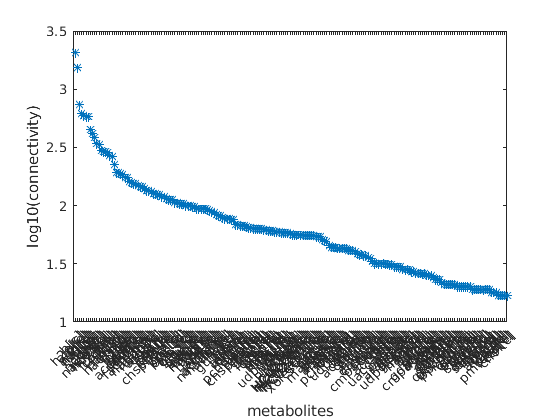

param.n=200;
[rankMetConnectivity,rankMetInd,rankConnectivity] = rankMetabolicConnectivity(stoichFluxThermoConsistModel,param);

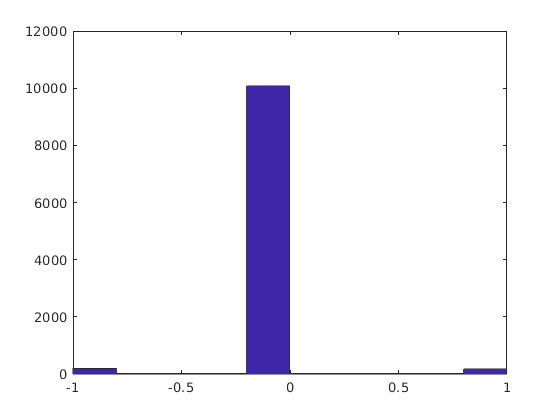

[nMet,nRxn]=size(stoichFluxThermoConsistModel.S);
rxnWeights=rand(nRxn,1)-0.5;
rxnWeights(stoichFluxThermoConsistModel.SConsistentRxnBool)=0;

coreRxnBool=rxnWeights<0.45;
removeRxnBool=rxnWeights>0.48;
rxnWeights(rxnWeights>0.4)=1;
rxnWeights(rxnWeights<-0.4)=-1;
rxnWeights(rxnWeights>=-0.4 & rxnWeights<=0.4)=0;
hist(rxnWeights)

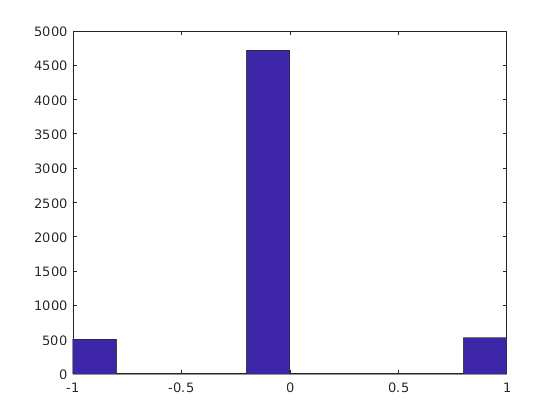

metWeights=rand(nMet,1)-0.5;
metWeights(rankMetInd(1:200))=0;
coreMetBool=metWeights<0.45;
removeMetBool=metWeights>0.5;
metWeights(metWeights>0.4)=1;
metWeights(metWeights<-0.4)=-1;
metWeights(metWeights>=-0.4 & metWeights<=0.4)=0;
hist(metWeights)

## Remove inactive reactions and absent metabolites

param.printLevel = 1;
[solverOK,solverInstalled]=changeCobraSolver('gurobi','QP');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > gurobi (version 811) is compatible and fully tested with MATLAB R2019a on your operating system.


[thermoFluxConsistentMetBool,thermoFluxConsistentRxnBool,stoichFluxThermoConsistModel,stoichFluxThermoConsistModelRed] = findThermoConsistentFluxSubset(stoichFluxThermoConsistModel, param, removeMetBool, removeRxnBool);

--- findThermoFluxConsistentSubset START ----
46 flux inconsistent metabolites
48 flux inconsistent reactions
                  printLevel: 1
                           n: 200
    normalizeZeroNormWeights: 0
                     epsilon: 1e-06
                 formulation: 'pqzw'
             iterationMethod: 'random'
                        nMax: 20
                 relaxBounds: 1
          acceptRepairedFlux: 1
             warmStartMethod: 'random'
             thetaMultiplier: 1.5
                       theta: 0.5
             regularizeOuter: 0
     thermoConsistencyMethod: 'cycleFreeFlux'
                      bigNum: 10000
                       debug: 0

optCardThermo objective data:
         0.1 = beta, the global weight on one-norm of internal reaction rate.
          -5 = min(g0), the local weight on zero-norm of internal reaction rate.
          -0 = max(g0), the local weight on zero-norm of internal reaction rate.
           0 = min(h0), the local weight on zero-norm of me

[nMet,nRxn]=size(stoichFluxThermoConsistModelRed.S)

nMet =         5633


nRxn =        10225


Remove the corresponding entries from the weights

bool = coreRxnBool & ~thermoFluxConsistentRxnBool;
if any(bool)
    fprintf('%u%s\n',nnz(bool), ' core reactions inconsistent due to removed reactions')
    if nnz(bool)<0
        stoichFluxThermoConsistModel.rxns{bool}
    end
end

183 core reactions inconsistent due to removed reactions


bool = coreMetBool & ~thermoFluxConsistentMetBool;
if any(bool)
    fprintf('%u%s\n',nnz(bool),' core metabolties inconsistent due to removed metabolites')
    if nnz(bool)<10
        stoichFluxThermoConsistModel.mets{bool}
    end
end

117 core metabolties inconsistent due to removed metabolites


rxnWeightsRed = rxnWeights(thermoFluxConsistentRxnBool);
metWeightsRed = metWeights(thermoFluxConsistentMetBool);
coreRxnBoolRed = coreRxnBool(thermoFluxConsistentRxnBool);
coreMetBoolRed = coreMetBool(thermoFluxConsistentMetBool);

## Compute the smallest thermodynamically consistent subnetwork containing a list of present metabolites and active reactions

activeInactiveRxn=coreRxnBoolRed;
presentAbsentMet=coreMetBoolRed;
activeInactiveRxn(:)=0;
presentAbsentMet(:)=0;
activeInactiveRxn(~stoichFluxThermoConsistModelRed.SConsistentRxnBool)=0;  
param.normalizeZeroNormWeights=0;

[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);

--- thermoKernel START ----
            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5
                      theta: 0.5
            regularizeOuter: 1
                    epsilon: 1e-06
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
          -1 = min(g0), the local weight on zero-norm of internal reaction rate.
           1 = max(g0), the local weight on zero-norm of internal reaction rate.
          -1 = min(h0), the local weight on zero-norm of metabolite production rate.
           1 = max(h0), the local weight on zero-norm of metabolite production rate.

optimizeCardinality objective data:

649 min cardinality variables:
           0 mean(c(p))	          -0 min(c(p))	   

[nMet,nRxn]=size(tissueModel.S)

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool);

#### Save weights

rxnWeightsRedTmp=rxnWeightsRed;
metWeightsRedTmp=metWeightsRed;
return

## Submodel with just metabolites specified

metWeightsRed=metWeightsRedTmp;
rxnWeightsRed(:)=0;
[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);
[nMet,nRxn]=size(tissueModel.S)

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool)

## Submodel with just reactions specified

rxnWeightsRed=rxnWeightsRedTmp;
metWeightsRed(:)=0;
[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);

[nMet,nRxn]=size(tissueModel.S)

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool)


## Submodel with just active metabolites specified

metWeightsRed=metWeightsRedTmp;
rxnWeightsRed(:)=0;
metWeightsRed(metWeightsRed>=0)=0;

[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);
[nMet,nRxn]=size(tissueModel.S)

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool)

## Submodel with just active reactions specified

rxnWeightsRed=rxnWeightsRedTmp;
metWeightsRed(:)=0;
rxnWeightsRed(rxnWeightsRed>=0)=0;
[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);

[nMet,nRxn]=size(tissueModel.S)

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModelRed, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool)